% FIRING RATE NETWORK MODEL FOR BUMP ATTRACTOR
% Continuous ring connectivity model

clear all;
close all;

## PARAMETERS

N = 500;          % Number of neurons in the rate model
T = 2 * pi / N;   % Sampling period  
L = N;            % Length of theta

npop = 8;         % Number of cues presented
totalTime = 1500; % Total time of the simulation in ms
dt = 2;           % Integration step in ms

tauE = 20;        % Time constant of rate equation for excitatory neurons
tauI = 10;        % Time constant of rate equation for inhibitory neurons

kappa = 1.5;      % Parameter defining concentration of e-to-e connectivity
GEE = 6;          % Strength of excitation to excitatory neurons
GEI = 4;          % Strength of excitation to inhibitory neurons
GIE = 3.4;        % Strength of inhibition to excitatory neurons
GII = 0.85;       % Strength of inhibition to inhibitory neurons

I0E = 0.2;        % External bias current to excitatory neurons
I0I = 0.5;        % External bias current to inhibitory neurons

sigE = 1;         % Standard deviation of additive noise in rate equation of e-cells
sigI = 3;         % Standard deviation of additive noise in rate equation of i-cells

stimon = 1000;    % Time when external stimulus is applied in ms
stimoff = 1500;   % Time when external stimulus ceases in ms
stim = 200;       % Strength of external stimulus
delayend = 3500;  % Time when delay ends in ms, and external input is applied to erase memory

## PRELIMINARY CALCULATIONS

rE = zeros(N, 1); % Initialize excitatory neurons' rates
rI = zeros(N, 1); % Initialize inhibitory neurons' rates
nsteps = floor(totalTime / dt); % Number of time steps

theta = [0:N-1] / N * 2 * pi; % Angular positions
v = exp(kappa * cos(theta));  % Gaussian tuning curve
v = v / sum(v);               % Normalize the tuning curve
WE = gallery('circul', v);    % Create circular connectivity matrix

## Zhang Model Parameters

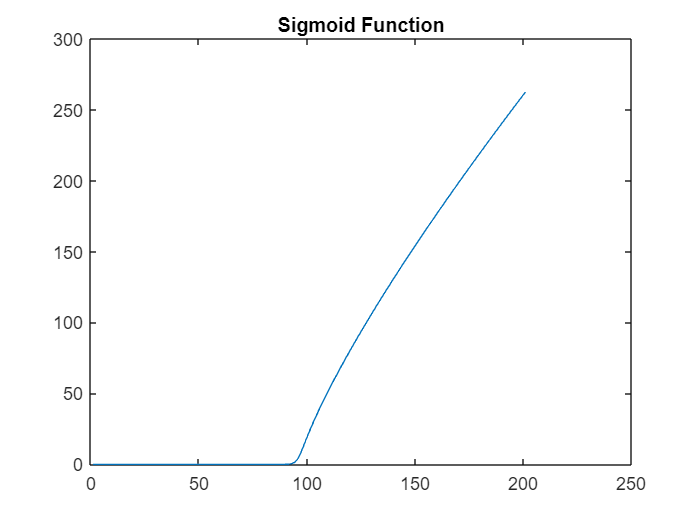

a = 6.34;
c = 0.5;
b = 10;
beta = 0.8;

A = 1;
K = 8;
B = 0.0131;
theta0 = 0;
F = @(x) A + B * exp(K * cos(x - theta0)); % Define function F

theta = [0:N-1] / N * 2 * pi - pi; % Shift theta to be centered around 0
f = F(theta); % Calculate f using function F

Sig = @(x) a * (log(1 + exp(b * (x + c)))).^beta; % Sigmoid function
x = -10:0.1:10;
plot(Sig(x));
title('Sigmoid Function');


syms x y
y1 = Sig(x);
U(x) = finverse(y1); % Inverse function of Sig
u = eval(U(f));

## Fourier Transform

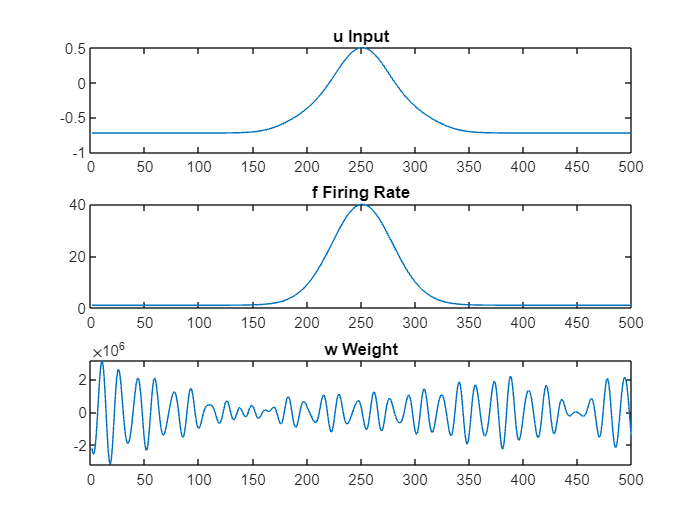

fn = fft(f); % Fourier transform of f
un = fft(u); % Fourier transform of u

wn = un ./ fn; % Calculate weight function in Fourier domain
wn(find(fn == 0)) = 0; % Set any infinities to zero

w = ifft(wn); % Inverse Fourier transform to get w in time domain

% Plot u, f, and w
figure;
subplot(3,1,1);
plot(u);
title('u Input');

subplot(3,1,2);
plot(f);
title('f Firing Rate');

subplot(3,1,3);
plot(w);
title('w Weight');

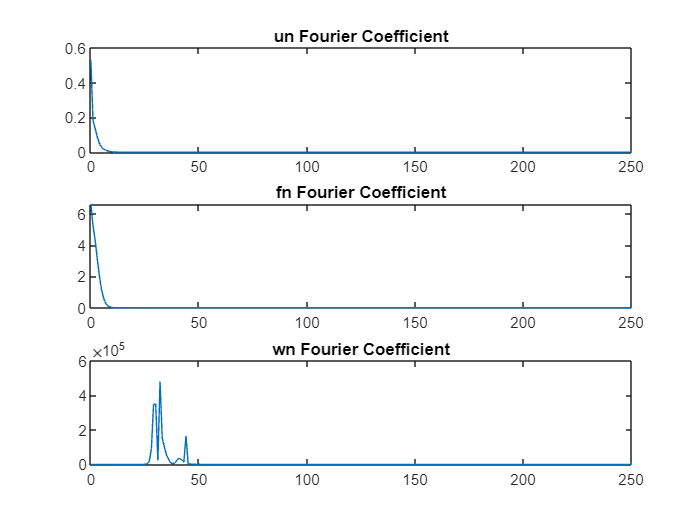


% Fourier Coefficients
freq = N * (0:(L/2)) / L;
figure;
subplot(3,1,1);
plot(freq, abs(un(1:L/2+1)) / L);
title('un Fourier Coefficient');

subplot(3,1,2);
plot(freq, abs(fn(1:L/2+1)) / L);
title('fn Fourier Coefficient');

subplot(3,1,3);
plot(freq, abs(wn(1:L/2+1)) / L);
title('wn Fourier Coefficient');

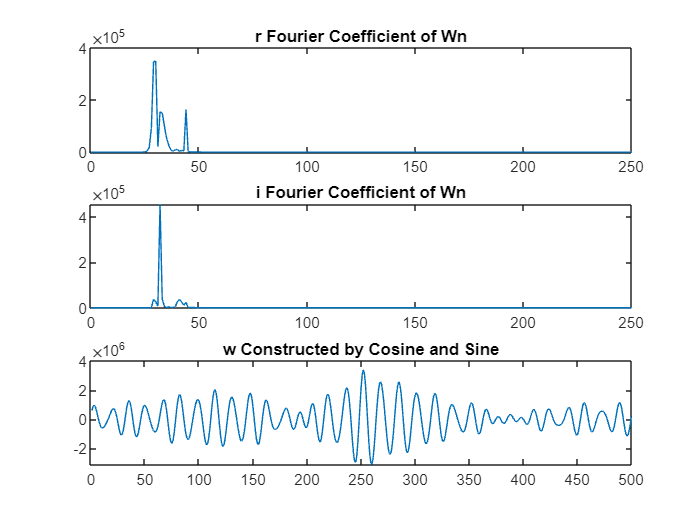


% Real and Imaginary Parts of Fourier Coefficients
r = abs(real(wn) / L);
i = abs(imag(wn) / L);

figure;
subplot(3,1,1);
plot(freq, r(1:L/2+1));
title('r Fourier Coefficient of Wn');

subplot(3,1,2);
plot(freq, i(1:L/2+1));
title('i Fourier Coefficient of Wn');

% Reconstruct the signal using Fourier components
X1 = zeros(1, L);

for m = 0:L/2-1
    X1 = X1 + 2 * r(m+1) * cos(m * N / L * theta) + 2 * i(m+1) * sin(m * N / L * theta);
end
subplot(3,1,3);
plot(X1);
title('w Constructed by Cosine and Sine');

sum(abs(w - X1));

## Test Fourier Transform Reconstruction

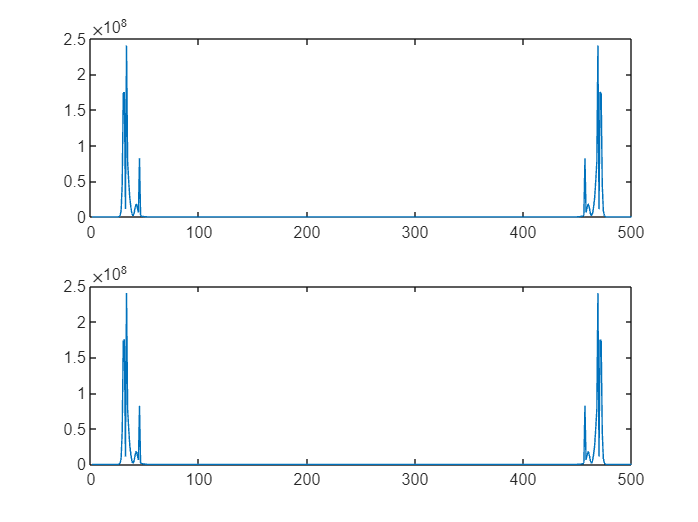

XX1 = fft(X1);
WWn = fft(w);
sum(abs(WWn) - abs(XX1));

figure;
title('Fourier Transform Reconstruction Test');
subplot(2,1,1);
plot(abs(WWn));
subplot(2,1,2);
plot(abs(XX1));

## Regularization

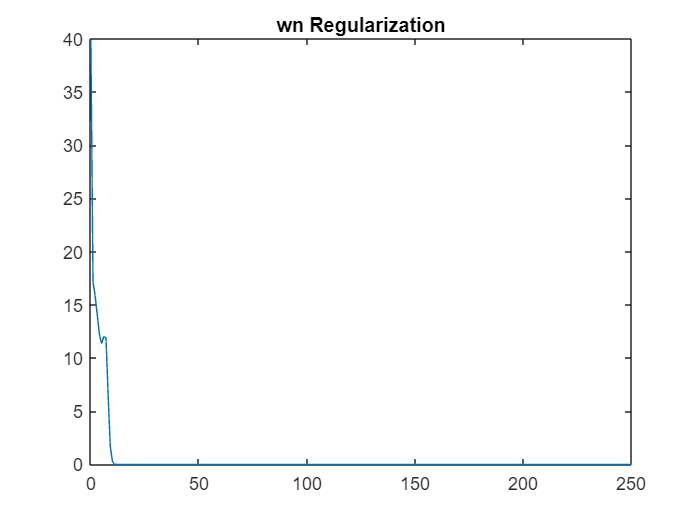

lamda0 = 1e-3;
lamda = max(abs(fn/L).^2) * lamda0;
wn_reg = un/L .* fn/L ./ (lamda + abs(fn/L).^2);
wn_reg = wn_reg * L;

figure;
plot(freq, abs(wn_reg(1:L/2+1)));
title('wn Regularization');

w_reg = ifft(wn_reg);

## Stimulus Parameters

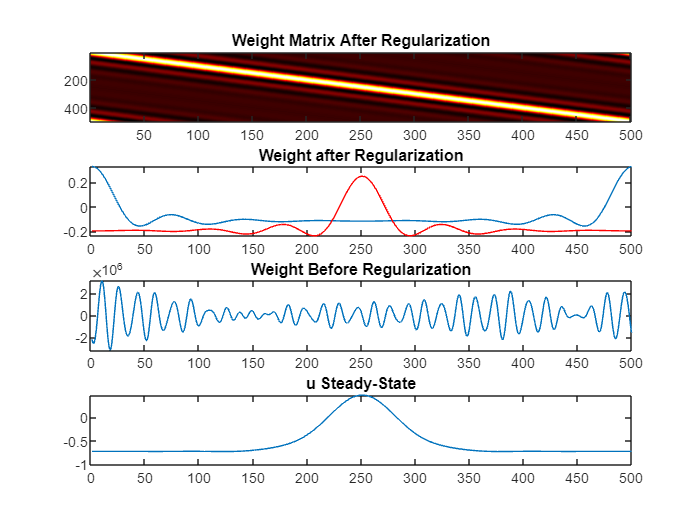

v = exp(kappa * cos(theta));
v = v / sum(v);
stimulus = stim * v';
stimon = floor(stimon / dt);
stimoff = floor(stimoff / dt);
delayend = floor(delayend / dt);
delaywin = floor(100 / dt); % 100 ms window

% Input-output function for all cells
F = inline('x.*x.*(x>0).*(x<1)+sqrt(4*x-3).*(x>=1)');

% Weight after regularization
W_reg = gallery('circul', w_reg);
W = gallery('circul', w);

figure;
subplot(4,1,1);
imagesc(W_reg);
colormap('hot');
title('Weight Matrix After Regularization');

subplot(4,1,2);
plot(w_reg);
title('Weight after Regularization');

% Real and Imaginary parts of wn_reg
r = real(wn_reg) / L;
i = imag(wn_reg) / L;
X1 = zeros(1, L);

for m = 0:L/2-1
    X1 = X1 + 2 * r(m+1) * cos(m * N / L * theta) + 2 * i(m+1) * sin(m * N / L * theta);
end
hold on;
plot(X1, 'r');

subplot(4,1,3);
plot(w);
title('Weight Before Regularization');

subplot(4,1,4);
plot(W_reg * f' / N);
title('u Steady-State');

## Assumption 1: Weight Modification

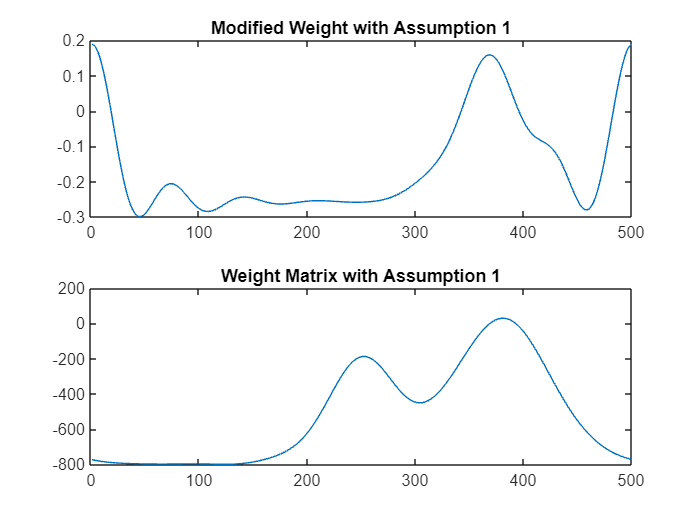

figure;
w_bihead = w_reg + circshift(u/3, +120) + 0.1;
subplot(2,1,1);
plot(w_bihead);
title('Modified Weight with Assumption 1');

W_bihead = gallery('circul', w_bihead);
subplot(2,1,2);
plot(W_bihead * f');
title('Weight Matrix with Assumption 1');

## Condition Number

ma2 = cond(w_reg);
ma1 = cond(gallery('circul', w));

## Singular Value Decomposition (SVD)

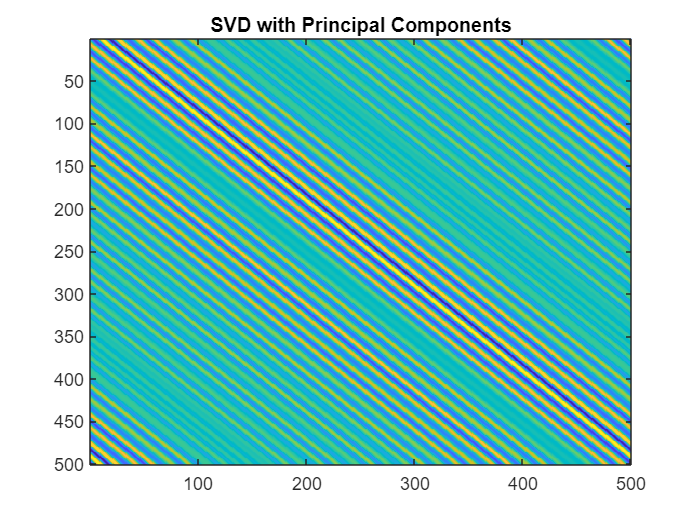

[U, s, v] = svd(W);

% Remove small singular values
lemt = 1000;
s_principal = s;
s_principal(find(s < lemt)) = 0;
W_principal = U * s_principal * v';

figure;
imagesc(W_principal);
title('SVD with Principal Components');


s1 = diag(1 ./ s(s > lemt));
s1(N, N) = 0;
x1 = v * s1 * U' * u';
y1 = W * x1;

## Local Stability of Static Activity Profile

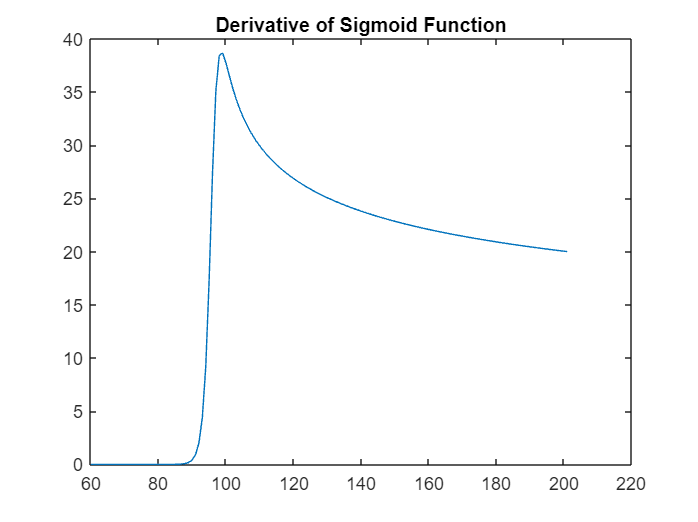

[V, D] = eig(W_reg);
Eigenvalue = D / N;

dsig = diff(Sig, x, 1);
x = -10:0.1:10;

figure;
plot(eval(dsig));
title('Derivative of Sigmoid Function');


x = u;
G = eval(dsig);
G = diag(G);

Aeig = -eye(N) + W_reg * G / N;  % Linear operator
[Eigenvector, Eigenvalues] = eig(Aeig);
Eigvalue_real = real(diag(Eigenvalues));

## Initial State and Simulation Loop

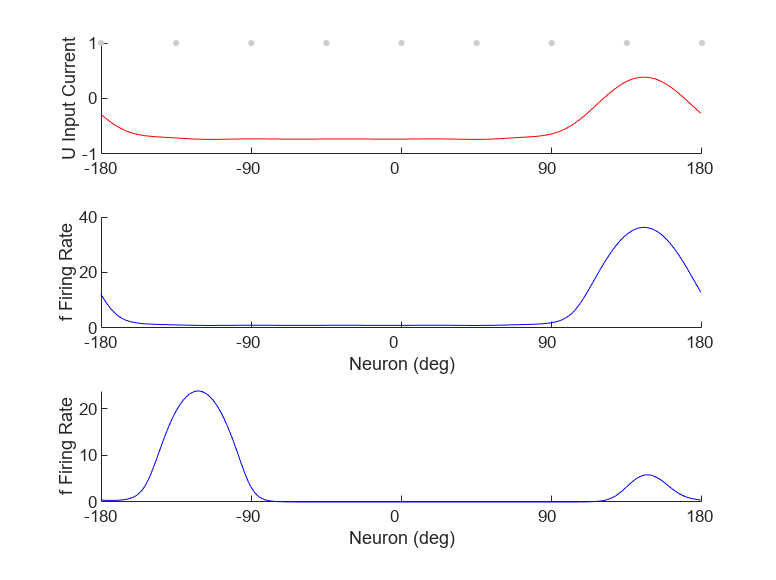

u = rand(N, 1); % Random initial phase
decode = inline('atan2(sum(r .* sin(th)), sum(r .* cos(th)))', 'r', 'th');

F = figure;
set(F, 'color', 'w');

H1 = subplot(3,1,1);
plot(([0:npop] - npop/2) / (npop/2) * pi, 1, '.k', 'markersize', 10, 'color', 0.8*[1 1 1], 'clipping', 'off');
xlim([-pi pi]);
ylabel('U Input Current');
set(H1, 'xtick', [-2:2] / 2 * pi);
set(H1, 'xticklabel', [-2:2] / 2 * 180);
box off;
hold on;

H2 = subplot(3,1,2);
ylabel('f Firing Rate');
xlabel('Neuron (deg)');
xlim([-pi pi]);
set(H2, 'xtick', [-2:2] / 2 * pi);
set(H2, 'xticklabel', [-2:2] / 2 * 180);
hold on;

H3 = subplot(3,1,3);
ylabel('f Firing Rate');
xlabel('Neuron (deg)');
xlim([-pi pi]);
set(H3, 'xtick', [-2:2] / 2 * pi);
set(H3, 'xticklabel', [-2:2] / 2 * 180);
hold on;

%%%% SIMULATION LOOP
u_bi=u;
for i = 1:nsteps
    noiseE = sigE * randn(N, 1);
    noiseI = sigI * randn(N, 1);
    
    fr = Sig(u);
    fr_bi = Sig(u_bi);
    
    I = W_reg * fr / N;
    I_bi = W_bihead * fr / N;
    

    
    % Euler integration with time-step dt
    u = u + (I - u) * dt / tauE;
    u_bi = u_bi + (I_bi - u_bi) * dt / tauE;
    
    if mod(i,5)==0
    % Graphical output
    subplot(H1);
    if exist('HP1', 'var'), delete(HP1), end
    HP1 = plot(theta, u, 'r', 'markersize', 10, 'markerfacecolor', 'k');
    
    subplot(H2);
    if exist('HP2', 'var'), delete(HP2), end
    HP2 = plot(theta, fr, 'b');
    
    subplot(H3);
    if exist('HP3', 'var'), delete(HP3), end
    HP3 = plot(theta, fr_bi, 'b');
    
    drawnow;
    end
end

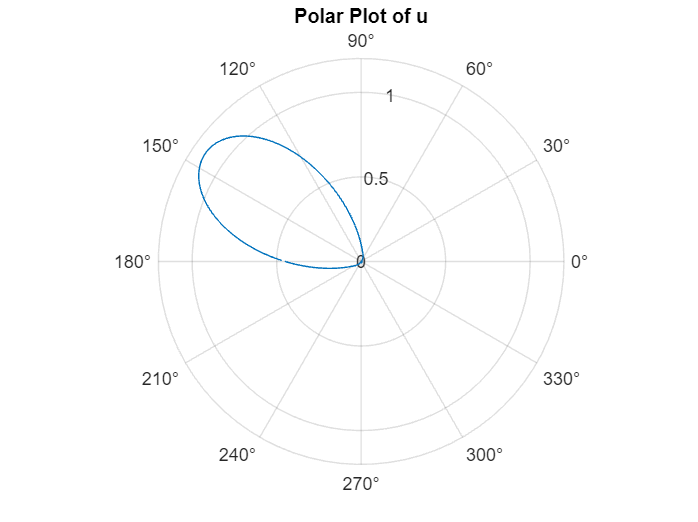


figure;
polarplot(theta, u' - min(u));
title('Polar Plot of u');

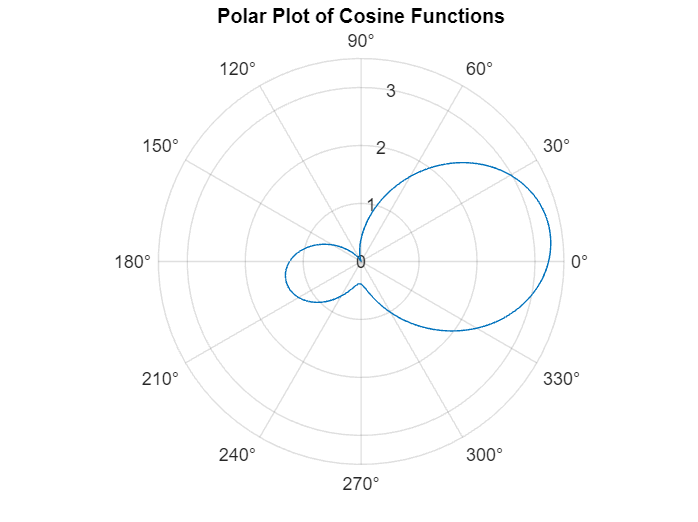


figure;
a = 0.2;
polarplot(theta, cos(theta) + cos(2 * (theta - a)) - min(cos(theta) + cos(2 * (theta - a))));
title('Polar Plot of Cosine Functions');